# File Name: Exercise_01_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## To do 1. load the teapot point cloud.

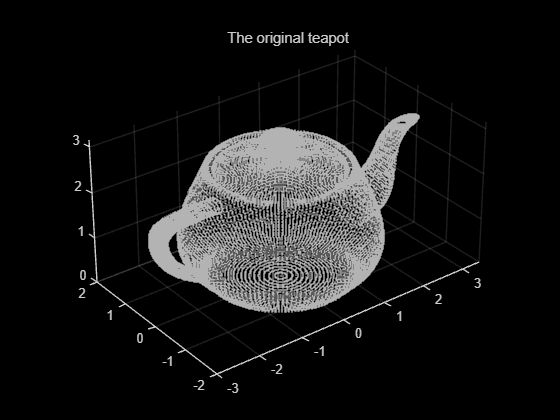

%%%%%%%%%% TODO %%%%%%%%%%
% read teapot using 'pcread'
ptCloud = pcread('teapot.ply');

% show the original teapot point cloud
figure(1);
pcshow(ptCloud.Location, [0.7, 0.7, 0.7]);
title('The original teapot');

## To do 2. Make two point cloud dividing it into upper and lower point clouds through search algorithm (findPointsInROI).

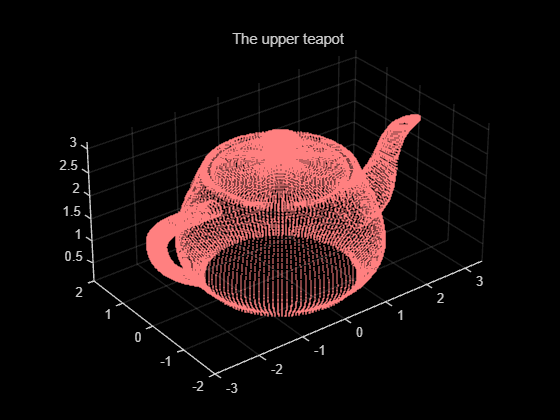

%%%%%%%%%% TODO %%%%%%%%%%
% set upper and lower ROIs
% ROI of upper point cloud: -4 m to 4 m for x-axis and y-axis, 0.1 m to 3.2 m for z-axis
% ROI of lower point cloud: -4 m to 4 m for x-axis and y-axis, 0   m to 2.8 m for z-axis
roiUpper = [-4 4 -4 4 0.1 3.2];
roiLower = [-4 4 -4 4 0 2.8];

%%%%%%%%%% TODO %%%%%%%%%%
% make upper and lower point clouds to registrer them after transformation using 'findPointsInROI' and 'select'
% Upper point cloud
indicesUpper = findPointsInROI(ptCloud,roiUpper);
ptCloudUpper = select(ptCloud,indicesUpper);

% Lower point cloud
indicesLower = findPointsInROI(ptCloud,roiLower);
ptCloudLower = select(ptCloud,indicesLower);


% show the upper and lowers
figure(2);
pcshow(ptCloudUpper.Location, [1, 0.5, 0.5]);
title('The upper teapot');

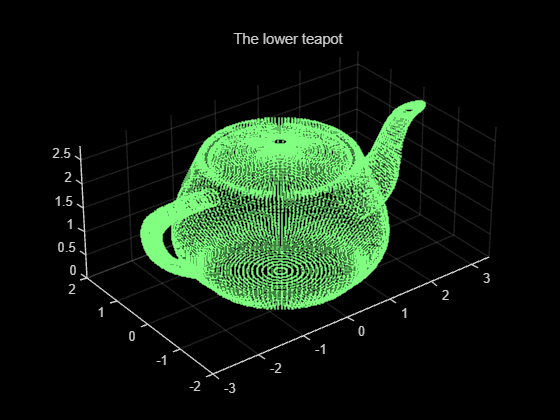


figure(3);
pcshow(ptCloudLower.Location, [0.5, 1, 0.5]);
title('The lower teapot');

## To do 3. Transform one of them (upper one).

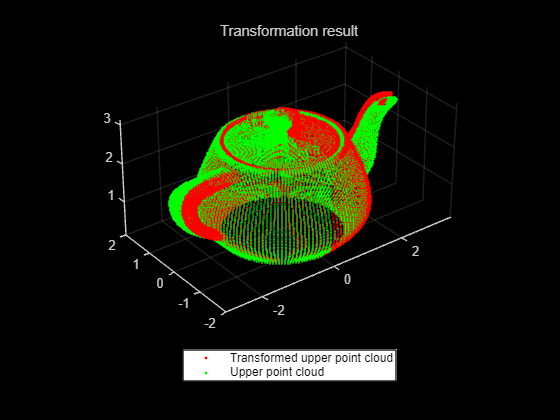

%%%%%%%%%% TODO %%%%%%%%%%
% Create an affine transform object that defines a 5 degree rotation along the z-axis, and 0.1 m translation along the x-axis.
R = [cosd(5) sind(5) 0 0; ...
    -sind(5) cosd(5) 0 0; ...
    0 0 1 0; ...
    0 0 0 1];
T = [1 0 0 0; ...
    0 1 0 0; ...
    0 0 1 0; ...
    0.1 0 0 1];

tform = affine3d(R*T);

%%%%%%%%%% TODO %%%%%%%%%%
% transform the upper point cloud using 'pctransform'
ptCloudUpperTF = pctransform(ptCloudUpper,tform);

% show the transformed upper point cloud
figure(4);
pcshow(ptCloudUpperTF.Location, 'r');
hold on;
pcshow(ptCloudUpper.Location , 'g');
legend('Transformed upper point cloud', 'Upper point cloud', 'Location', 'southoutside', 'Color', [1 1 1]);
title('Transformation result');